% =========================================================================
% Ryan Mittelstadt 
% Low Thrust Trajectory Optimizer: Earth to Comet 29P
% =========================================================================
clc; clear; close all;
format short g;

% Define Physics Constants
const.Re_km   = 149597870.7;        % 1 Astronomical Unit[km]
const.mu_sun  = 132712440041.279;   % Sun's Gravitational Parameter [km^3/s^2]
const.g0_km   = 9.807 / 1000;       % Standard Gravity [km/s^2]

% Canonical Units
units.DU = const.Re_km;                     % Distance Unit [km]
units.TU = sqrt(units.DU^3 / const.mu_sun); % Time Unit [s]
units.VU = units.DU / units.TU;             % Velocity Unit [km/s]

% Spacecraft Parameters
sc.m0_kg     = 5000;     % Wet Mass [kg]
sc.T_N       = 1.0;      % Thrust [N]
sc.Isp       = 4100;     % Specific Impulse [s]
sc.Area      = 25.0;     % SRP Area [m^2]
sc.P_1AU_Pa  = 6.75e-6;  % Solar Pressure @ 1AU [Pa]

% -------------------------------------------------------------------------
% DATA CONVERSION: Physical -> Canonical
% -------------------------------------------------------------------------
% Compute normalized Thrust, Mass Flow, and SRP Acceleration
mission.T    = (sc.T_N/1000) * (units.TU^2 / (sc.m0_kg * units.DU));     % Nondim. Thrust
mission.mdot = (sc.T_N/1000) / (sc.Isp * const.g0_km) * (units.TU / sc.m0_kg); % Nondim. Mass Flow
mission.SRP  = (sc.P_1AU_Pa * sc.Area / 1000) * (units.TU^2 / (sc.m0_kg * units.DU)); % Nondim. SRP

% --- INITIAL STATE ---
R_E_vec_km = [44501546.2560627; 140562393.107815]; % Earth Position Vector [km]

% Construct Initial State Vector [r, theta, u, v]
y0 = [ norm(R_E_vec_km)/units.DU; ...              % Radius (r)
       atan2(R_E_vec_km(2), R_E_vec_km(1)); ...    % Angle (theta)
       0.0; ...                                    % Radial Velocity (u)
       sqrt(units.DU/norm(R_E_vec_km)) ];          % Tangential Velocity (v)

% --- TARGET DATA (COMET 29P) ---
R_P_vec_km = [752948956.855689; -426824160.469468]; % 29P Position Vector [km]
theta_P_init = atan2(R_P_vec_km(2), R_P_vec_km(1)); % Initial Comet Angle

% --- SOLVER CONFIGURATION ---
target = 5.79; % Target Radius [AU]

% Solver Options (High Precision)
opts = optimoptions('fsolve', 'Display', 'iter', 'TolFun', 1e-6, 'TolX', 1e-6);

% -------------------------------------------------------------------------
% PART A: SOLVE OPTION 1 (NO SOLAR PRESSURE)
% -------------------------------------------------------------------------
fprintf('\n--- OPTION 1: NO SOLAR PRESSURE ---\n');


--- OPTION 1: NO SOLAR PRESSURE ---



mission_opt1 = mission;
mission_opt1.SRP = 0.0; % Disable SRP

% Initial Guess: [lr, lth, lu, lv, tf]
% Strategy: Dive for Oberth Maneuver
guess_init = [0.2;        % Radial Costate (Dive bias)
              0;          % Angle Costate (Cyclic)
              0;          % Radial Vel Costate
              -2.0;       % Tangential Vel Costate
              2*2*pi];    % Flight Time (~2 years)

[SOL_OPT1, success1] = RunSolver(y0, target, theta_P_init, guess_init, mission_opt1, opts);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          6             37.7599                            7.61              1
     1         12             19.9715              1             9.98              1
     2         18             15.0327            2.5             1.46            2.5
     3         19             15.0327           6.25             1.46           6.25
     4         25             14.6876         1.5625             8.01           1.56
     5         31             10.5702         1.5625             5.69           1.56
     6         32             10.5702        3.90625             5.69           3.91
     7         38             10.0638       0.976562             6.31          0.977
     8         44             8.19334       0.976562              4.3          0.977
     9         45             8.19334        2.44141            


%% -------------------------------------------------------------------------
%% PART B: OPTION 2 (WITH SOLAR PRESSURE)
%% -------------------------------------------------------------------------
fprintf('\n--- OPTION 2: WITH SOLAR PRESSURE ---\n');


--- OPTION 2: WITH SOLAR PRESSURE ---



mission_opt2 = mission; 
guess_init = [0.2;        % Radial Costate
              0;          % Angle Costate
              0;          % Radial Vel Costate
              -2.0;       % Tangential Vel Costate
              2*2*pi];    % Flight Time

[SOL_OPT2, success2] = RunSolver(y0, target, theta_P_init, guess_init, mission_opt2, opts);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          6             37.7592                            7.61              1
     1         12             19.9736              1             9.99              1
     2         18             15.0322            2.5             1.46            2.5
     3         19             15.0322           6.25             1.46           6.25
     4         25             14.6869         1.5625             8.01           1.56
     5         31             10.5694         1.5625             5.69           1.56
     6         32             10.5694        3.90625             5.69           3.91
     7         38             10.0631       0.976563             6.31          0.977
     8         44              8.1929       0.976563              4.3          0.977
     9         45              8.1929        2.44141            

 FINAL MISSION REPORT



>>> Option 1: Engines Only


Mission Time:      3.8348 Years


Final Dry Mass:    1990.22 kg


Propellant Used:   3009.78 kg


-------------------------------------------------------------------------


INERTIAL PARAM     | SPACECRAFT       | TARGET           | ERROR


-------------------|------------------|------------------|---------------


Pos X (m)          |     3.0275e+11   |     3.0275e+11   |     0.0253


Pos Y (m)          |     8.1154e+11   |     8.1154e+11   |    -0.0243


Vel X (m/s)        |    -11597.3676   |    -11597.3676   |   7.88e-10


Vel Y (m/s)        |      4326.4665   |      4326.4665   |  -8.47e-10


------------------------------------------------------------


RELATIVE STATE (LVLH wrt Target)


------------------------------------------------------------


Radial Pos (cm)    :      -1.390646


Along-Track (cm)   :      -3.222265


Radial Vel (cm/s)  :      -0.000000


Along-Track (cm/s) :      -0.000000


------------------------------------------------------------


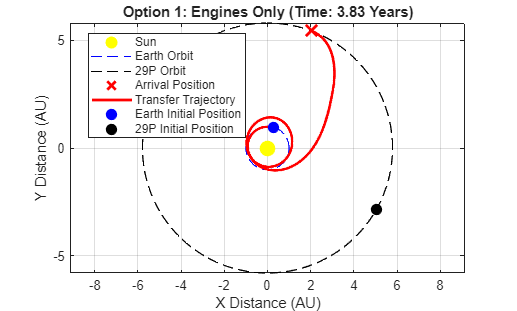

 FINAL MISSION REPORT



>>> Option 2: Engines + Solar Pressure


Mission Time:      3.8348 Years


Final Dry Mass:    1990.22 kg


Propellant Used:   3009.78 kg


-------------------------------------------------------------------------


INERTIAL PARAM     | SPACECRAFT       | TARGET           | ERROR


-------------------|------------------|------------------|---------------


Pos X (m)          |     3.0275e+11   |     3.0275e+11   |     0.0435


Pos Y (m)          |     8.1154e+11   |     8.1154e+11   |     0.0135


Vel X (m/s)        |    -11597.3761   |    -11597.3761   |   9.48e-10


Vel Y (m/s)        |      4326.4439   |      4326.4439   |   9.51e-10


------------------------------------------------------------


RELATIVE STATE (LVLH wrt Target)


------------------------------------------------------------


Radial Pos (cm)    :       2.788447


Along-Track (cm)   :      -3.598010


Radial Vel (cm/s)  :       0.000000


Along-Track (cm/s) :      -0.000000


------------------------------------------------------------


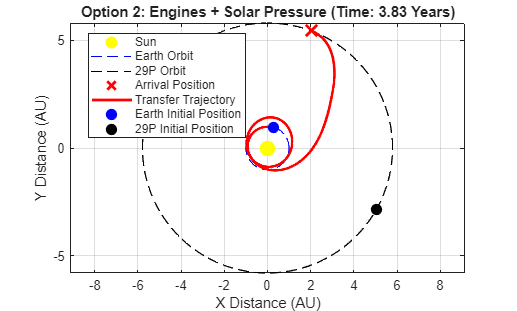


% -------------------------------------------------------------------------
% 3. FINAL OUTPUTS & REPORTING
% -------------------------------------------------------------------------

% Plotting Constants (Vectors for plotting)
R_E_plt = R_E_vec_km / units.DU; 
R_P_plt = R_P_vec_km / units.DU;

% Store results in struct array for iteration
runs = struct('sol', {SOL_OPT1, SOL_OPT2}, ...
              'mission', {mission_opt1, mission_opt2}, ...
              'name', {'Option 1: Engines Only', 'Option 2: Engines + Solar Pressure'});

% Tight propagation tolerances
prop_opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);


for k = 1:length(runs)
    if isempty(runs(k).sol)
        fprintf('\n!! %s FAILED TO CONVERGE !!\n', runs(k).name);
        continue; 
    end

    curr_sol = runs(k).sol;
    curr_mis = runs(k).mission;
    
    % Unpack Solution Vector
    tf = curr_sol(5);
    L_costates = [curr_sol(1); curr_sol(2); curr_sol(3); curr_sol(4)];
    
    % Propagate Full Trajectory
    [t_out, y_out] = ode45(@(t,y) Dynamics(t, y, curr_mis), [0 tf], [y0; L_costates], prop_opts);
    
    % --- Post-Processing ---
    % Calculate Mass Usage
    m_rem = (1.0 - curr_mis.mdot * t_out(end)) * sc.m0_kg; % Remaining Dry Mass [kg]
    m_used = sc.m0_kg - m_rem;                             % Propellant Consumed [kg]
    time_yrs = tf/(2*pi);                                  % Duration [Years]
    
    % Extract Final State
    r_act = y_out(end,1);     % Final Radius
    theta_f = y_out(end,2);   % Final Angle
    u_act = y_out(end,3);     % Final Radial Vel
    v_act = y_out(end,4);     % Final Tangential Vel
    
    % --- TRUE TARGET STATE CALCULATION ---
    % Comet orbital parameters
    r_tgt = 5.79;                       % Target Radius
    v_tgt_mag = sqrt(1/r_tgt);          % Target Velocity Magnitude
    omega_tgt = v_tgt_mag / r_tgt;      % Target Angular Velocity
    
    % Calculate Comet position at arrival time tf
    theta_tgt_final = theta_P_init + omega_tgt * tf;
    
    % --- COORDINATE TRANSFORMATION (Canonical -> m, m/s) ---
    % Spacecraft Inertial Position [m]
    x_act_m = (r_act * cos(theta_f)) * units.DU * 1000;
    y_act_m = (r_act * sin(theta_f)) * units.DU * 1000;
    
    % Target Inertial Position [m]
    x_tgt_m = (r_tgt * cos(theta_tgt_final)) * units.DU * 1000;
    y_tgt_m = (r_tgt * sin(theta_tgt_final)) * units.DU * 1000;
    
    % Spacecraft Inertial Velocity [m/s]
    vx_act_ms = (u_act * cos(theta_f) - v_act * sin(theta_f)) * units.VU * 1000;
    vy_act_ms = (u_act * sin(theta_f) + v_act * cos(theta_f)) * units.VU * 1000;
    
    % Target Inertial Velocity [m/s]
    vx_tgt_ms = (0 * cos(theta_tgt_final) - v_tgt_mag * sin(theta_tgt_final)) * units.VU * 1000;
    vy_tgt_ms = (0 * sin(theta_tgt_final) + v_tgt_mag * cos(theta_tgt_final)) * units.VU * 1000;
    
    % --- LVLH Conversions ---
    % Calculate Inertial Differences [m, m/s]
    diff_r_inertial = [x_act_m - x_tgt_m;  y_act_m - y_tgt_m];
    diff_v_inertial = [vx_act_ms - vx_tgt_ms; vy_act_ms - vy_tgt_ms];
    
    % Rotation Matrix (Inertial -> LVLH) based on Target Angle
    c_th = cos(theta_tgt_final); 
    s_th = sin(theta_tgt_final);
    Q_rot = [ c_th,  s_th; 
             -s_th,  c_th]; 
             
    % Rotate into Relative Frame
    rel_pos_lvlh = Q_rot * diff_r_inertial; 
    rel_vel_lvlh = Q_rot * diff_v_inertial; 
    
    % --- CONSOLE REPORT ---
    fprintf('\n==========================================================\n');
    fprintf(' FINAL MISSION REPORT\n');
    fprintf('============================================================\n');
    fprintf('\n>>> %s\n', runs(k).name);
    fprintf('Mission Time:      %.4f Years\n', time_yrs);
    fprintf('Final Dry Mass:    %.2f kg\n', m_rem);
    fprintf('Propellant Used:   %.2f kg\n', m_used);
    fprintf('-------------------------------------------------------------------------\n');
    fprintf('INERTIAL PARAM     | SPACECRAFT       | TARGET           | ERROR\n');
    fprintf('-------------------|------------------|------------------|---------------\n');
    fprintf('Pos X (m)          | %14.4e   | %14.4e   | %10.4f\n', x_act_m, x_tgt_m, x_act_m - x_tgt_m); 
    fprintf('Pos Y (m)          | %14.4e   | %14.4e   | %10.4f\n', y_act_m, y_tgt_m, y_act_m - y_tgt_m);
    fprintf('Vel X (m/s)        | %14.4f   | %14.4f   | %10.2e\n', vx_act_ms, vx_tgt_ms, vx_act_ms - vx_tgt_ms);
    fprintf('Vel Y (m/s)        | %14.4f   | %14.4f   | %10.2e\n', vy_act_ms, vy_tgt_ms, vy_act_ms - vy_tgt_ms);
    fprintf('------------------------------------------------------------\n');
    fprintf('RELATIVE STATE (LVLH wrt Target)\n');
    fprintf('------------------------------------------------------------\n');
    fprintf('Radial Pos (cm)    : %14.6f\n', rel_pos_lvlh(1) * 100); 
    fprintf('Along-Track (cm)   : %14.6f\n', rel_pos_lvlh(2) * 100);
    fprintf('Radial Vel (cm/s)  : %14.6f\n', rel_vel_lvlh(1) * 100); 
    fprintf('Along-Track (cm/s) : %14.6f\n', rel_vel_lvlh(2) * 100);
    fprintf('------------------------------------------------------------\n');
    
    % --- PLOTTING ---
    figure('Name', runs(k).name, 'Color', 'w');
    
    % Convert Polar to Cartesian for Plot
    r = y_out(:,1); 
    theta = y_out(:,2);
    X = r .* cos(theta); 
    Y = r .* sin(theta);
    
    % Plot Sun
    plot(0,0,'y.','MarkerSize',35); 
    hold on; axis equal; grid on;
    
    % Plot Orbits
    th_plot = linspace(0,2*pi,200);
    plot(cos(th_plot), sin(th_plot), 'b--');              % Earth Orbit
    plot(5.79*cos(th_plot), 5.79*sin(th_plot), 'k--');    % 29P Orbit
    
    % Plot Actual Target Location at Arrival
    xt = 5.79*cos(theta_tgt_final); 
    yt = 5.79*sin(theta_tgt_final);
    plot(xt, yt, 'rx', 'MarkerSize', 12, 'LineWidth', 2);
    
    % Plot Trajectory
    plot(X, Y, 'r-', 'LineWidth', 2);                         
    
    % Plot Initial Positions
    plot(R_E_plt(1), R_E_plt(2), 'bo', 'MarkerSize', 8, 'MarkerFaceColor','b'); % Earth Init
    plot(R_P_plt(1), R_P_plt(2), 'ko', 'MarkerSize', 8, 'MarkerFaceColor','k'); % 29P Init
    
    
    title([runs(k).name ' (Time: ' num2str(time_yrs, '%.2f') ' Years)']);
    legend('Sun', ...
           'Earth Orbit', ...
           '29P Orbit', ...
           'Arrival Position', ...
           'Transfer Trajectory', ...
           'Earth Initial Position', ...
           '29P Initial Position', ...
           'Location','best');
    xlabel('X Distance (AU)'); ylabel('Y Distance (AU)');
end


% =======================================================================
%  HELPER FUNCTIONS
%  ======================================================================

% RunSolver: Wrapper for fsolve
function [final_sol, success] = RunSolver(y0, target, th_tgt_0, guess, mission, opts)
    
    % Prepare target variables
    r_targ = target; 
    v_targ = sqrt(1/r_targ); 
            
    % Define anonymous function to pass parameters
    target_fun = @(x) Objective_Function(x, y0, r_targ, v_targ, th_tgt_0, mission);
    [sol, ~, exitflag] = fsolve(target_fun, guess, opts);
    
    if exitflag > 0
        fprintf('OK. (%.2f Yrs)\n', sol(5)/(2*pi));
        final_sol = sol;     
        success = true;
    else
        fprintf('FAILED.\n'); 
        final_sol = [];
        success = false;
    end
end

% Objective Function: Defines Boundary Value Problem (BVP) Errors
function err = Objective_Function(x, y0, rf_des, vf_des, th_tgt_0, m)
    % Unpack Decision Variables
    lr = x(1);    % Radial Costate
    lth = x(2);   % Angle Costate
    lu = x(3);    % Radial Velocity Costate
    lv = x(4);    % Tangential Velocity Costate
    tf = max(x(5), 0.1); % Flight Time (Enforce positive)
    
    % High Precision Integration Options
    opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);
    
    % Propagate State & Costates
    [~, Y] = ode45(@(t,y) Dynamics(t, y, m), [0 tf], [y0; lr; lth; lu; lv], opts);
    
    % Extract Final State
    r_f = Y(end, 1);      % Final Radius
    theta_f = Y(end, 2);  % Final Angle
    u_f = Y(end, 3);      % Final Radial Velocity
    v_f = Y(end, 4);      % Final Tangential Velocity
    
    % Extract Final Costates
    lr_f = Y(end, 5);     % Final Radial Costate
    lth_f = Y(end, 6);    % Final Angle Costate
    lu_f = Y(end, 7);     % Final Radial Vel Costate
    lv_f = Y(end, 8);     % Final Tangential Vel Costate
    m_f  = 1-m.mdot * tf; % Final Mass Fraction
    
    % --- TARGET MOTION CALCULATION ---
    % Calculate where target is on its orbit at time tf
    omega_tgt = vf_des / rf_des; 
    theta_tgt_final = th_tgt_0 + omega_tgt * tf;
    
    % Angle Error (Wrapped to -pi, pi)
    d_theta = mod(theta_f - theta_tgt_final, 2*pi);
    if d_theta > pi
        d_theta = d_theta - 2*pi; 
    end
    
    % Optimal Control Direction (Primer Vector)
    den = sqrt(lu_f^2 + lv_f^2); 
    if den==0
        den=1; % Avoid division by zero
    end
    sin_a = -lu_f / den; % Steering angle sin
    cos_a = -lv_f / den; % Steering angle cos
    
    % Acceleration Terms
    accel_srp = m.SRP / (m_f * r_f^2); 
    
    % Hamiltonian Calculation (H = -1 for Minimum Time)
    H_final = lr_f*u_f + lth_f*(v_f/r_f) + ... 
              lu_f*(v_f^2/r_f - 1/r_f^2 + accel_srp + (m.T/m_f)*sin_a) + ...
              lv_f*(-u_f*v_f/r_f + (m.T/m_f)*cos_a);
    
    % Return 5 Errors [Radius, Angle, RadialVel, TangentialVel, Hamiltonian]
    err = [ r_f - rf_des; 
            d_theta;       
            u_f; 
            v_f - vf_des; 
            H_final + 1 ];   
end

% Dynamics: System of First-Order ODEs (State + Costates)
function dy = Dynamics(t, y, m)
    % Unpack State
    r = y(1);    % Radius
    u = y(3);    % Radial Velocity
    v = y(4);    % Tangential Velocity
    
    % Unpack Costates
    l_r = y(5);   % Radial Costate
    l_th = y(6);  % Angle Costate
    l_u = y(7);   % Radial Vel Costate
    l_v = y(8);   % Tangential Vel Costate
    
    % Mass & Environment
    m_curr = 1.0 - m.mdot * t;          % Current Mass
    accel_srp = m.SRP / (m_curr * r^2); % SRP Acceleration
    
    % Optimal Control Law
    den = sqrt(l_u^2 + l_v^2);
    if den == 0
        sin_a = 0; 
        cos_a = 1; 
    else
        sin_a = -l_u / den; 
        cos_a = -l_v / den;
    end
    
    % Equations of Motion (EOM)
    d_r = u; 
    d_th = v/r;
    d_u = v^2/r - 1/r^2 + accel_srp + (m.T/m_curr)*sin_a; 
    d_v = -u*v/r + (m.T/m_curr)*cos_a;                    
    
    % Euler-Lagrange Costate Equations
    d_l_r = l_th*(v/r^2) + l_u*(v^2/r^2 - 2/r^3 + 2*accel_srp/r) - l_v*(u*v/r^2);
    d_l_th = 0; 
    d_lu = -l_r + l_v*(v/r);
    d_lv = -l_th/r - l_u*(2*v/r) + l_v*(u/r);
    
    % Pack Derivative Vector
    dy = [d_r; d_th; d_u; d_v; d_l_r; d_l_th; d_lu; d_lv];
end